%compare beam squint compensation between different method
clc;
clear all;
close all;

B = 1e9.*[30,40,60];
%B =1e9.*30; 
g0 = 0.9; 

%% system parameters
Sysparam = struct();

Sysparam.Nt = 720;
Mset =divisors(Sysparam.Nt);
Sysparam.Nr = 4;
Sysparam.Ns = 4;
Sysparam.fc = 3e11;%carrier frequency 
BRatio = B./Sysparam.fc;
Sysparam.K = 129;  %number of sub-carriers
Sysparam.L = 1 ; % number of paths equals to number of RF chains
%%
%% simulation parameters
Simparam = struct();
Simparam.psi = pi*rand(Sysparam.L,1)-0.5*pi; %AoA;
Simparam.Niter = 100; %channel realizations
Simparam.phi = 0.2951*pi*ones(Sysparam.L,1);%AoD;
SpatialDirection = sin(Simparam.phi)

SpatialDirection = 0.7999

for i = 1:length(B)
Omega(i) = 6*(1-g0)/(pi*(Sysparam.K-1)*BRatio(i)*0.8/(4*Sysparam.K))^2;
Mtemp(i) = Sysparam.Nt/sqrt(1+Omega(i));    
mIndex = find(Mset > Mtemp(i));
Mstar(i) = Mset(mIndex(1)); %number of TTDs for each RF chain
Msub(i) = Mset(mIndex(1)-1);
Msup(i) = Mset(mIndex(1)+1);
end
Mtemp 

Mtemp =    57.7637   76.8262  114.4279


Msub

Msub =     48    72    90


Mstar

Mstar =     60    80   120


Msup

Msup =     72    90   144


%% 
for i = 1:length(B)
Sysparam.f = B(i); %bandwidth
%Sysparam.M = Mstar(i); %number of TTDs for each RF chain
Sysparam.M = Msup(i); %number of TTDs for each RF chain
%Sysparam.M = 30; %number of TTDs for each RF chain
%Sysparam.M = Msub(i); %number of TTDs for each RF chain
%Sysparam.M = 48; %number of TTDs for each RF chain
Sysparam.N = Sysparam.Nt/Sysparam.M; %number of PSs for each TTD
Sysparam.tmax = max(sin(Simparam.phi))*((2*Sysparam.M-1)*Sysparam.Nt-Sysparam.M)/(4*Sysparam.M*Sysparam.fc);
%% Sub-carrier frequencies
for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 
%Generate wideband channel
[PS,TTD,x,t] = jointPSandTTD(Sysparam, Simparam); % joint delay and phase precoding
for l = 1:Sysparam.L
    a(:,l) = arrayResponse(sin(Simparam.phi(l)),Sysparam.Nt);
    for k = 1:Sysparam.K
         b(:,k,l) = arrayResponse(Sysparam.xi(k)*sin(Simparam.phi(l)),Sysparam.Nt);
         arrayGain(k,l,i) = abs(a(:,l)'*b(:,k,l));
         Compensated1(k,l,i) = abs((PS*TTD(:,l,k))'*b(:,k,l));
         %Compensated2(k,l,i) = abs((G1*G2k(:,l,k))'*b(:,k,l));          
         %Compensated3(k,l,i) = abs((S*F2k(:,l,k))'*b(:,k,l));
    end
end
clear a b ;
end 

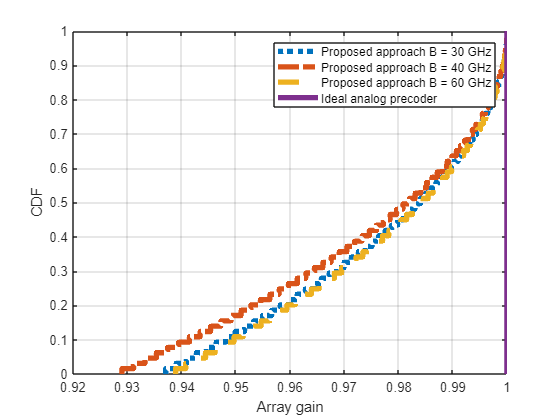

close all;
figure(1)
f1 = cdfplot(Compensated1(:,:,1));
set(f1,'LineWidth',4,'LineStyle',':','Marker','none');
hold on
f2 = cdfplot(Compensated1(:,:,2));
set(f2,'LineWidth',4,'LineStyle','-.','Marker','none');
hold on
f3 = cdfplot(Compensated1(:,:,3));
set(f3,'LineWidth',4,'LineStyle','--','Marker','none');
hold on
f4 = cdfplot(ones(Sysparam.K,1));
set(f4,'LineWidth',4,'LineStyle','-','Marker','none');
legend('Proposed approach B = 30 GHz','Proposed approach B = 40 GHz','Proposed approach B = 60 GHz','Ideal analog precoder')
xlabel('Array gain')
ylabel('CDF')
title('')